# Laboratorio 2

**Diego Carvajal - Duvan Lizarazo**

## **Importar base de datos de Hepatitis**

datafile = pwd + "\hepatiti.pat";
hepatiti = importHepatitis(datafile);
hepatiti = table2array(hepatiti);

## Separar datos de entrenamiento y test

Dividir el 70% de los datos de forma aleatoria para entrenamiento y el 30% restante para pruebas

[m,~] = size(hepatiti);
train_index = randperm(m,floor(m*0.7));
test_index = setdiff(1:m,train_index);

train_data = hepatiti(train_index,:);
test_data = hepatiti(test_index,:);

Separar las columnas de variables de las de clases

train_var = train_data(:,1:end-2);
train_mclass = train_data(:,end-1:end);

test_var = test_data(:,1:end-2);
test_class = test_data(:,end-1:end);

## Calcular los centroides de cada clase

train_c1 = train_var(train_class(:,1) == 0 & train_class(:,2) == 1,:);
cent_train_c1 = mean(train_c1);
train_c2 = train_var(train_class(:,1) == 1 & train_class(:,2) == 0,:);
cent_train_c2 = mean(train_c2);

## Distancia Euclídea

### Predicción

#### Predicción datos de entrenamiento

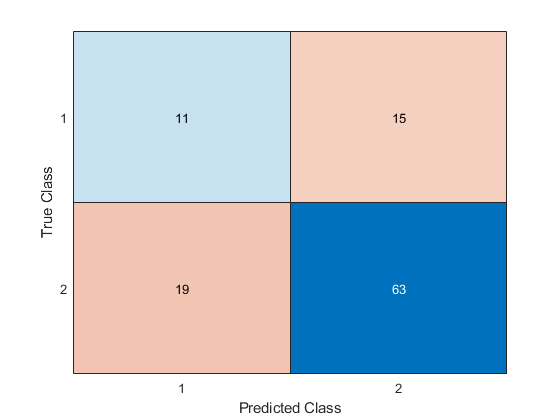

[trm,trn] = size(train_class);
train_vclass = zeros(trm,1);
for i=1:trm
    if train_class(i,1)==0 && train_class(i,2)==1
        train_vclass(i,1) = 1;
    else
        train_vclass(i,1) = 2;
    end
end
train_pclass = zeros(trm,1);
for i=1:trm
    if pdist2(cent_train_c1,train_var(i,:)) < pdist2(cent_train_c2,train_var(i,:))
        train_pclass(i,1) = 1;
    else
        train_pclass(i,1) = 2;
    end
end
train_conf = confusionmat(train_vclass,train_pclass);
confusionchart(train_conf)

#### Prediccion de datos de prueba

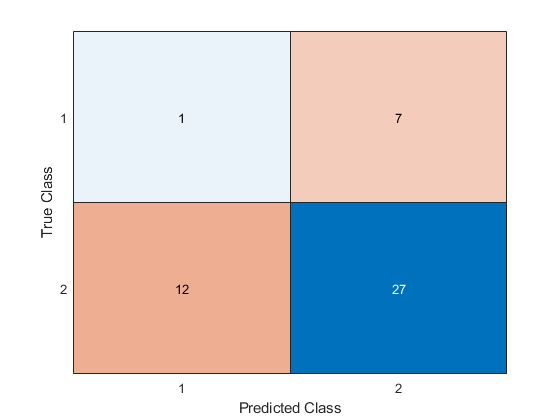

[tsm,tsn] = size(test_class);
test_vclass = zeros(tsm,1);
for i=1:tsm
    if test_class(i,1)==0 && test_class(i,2)==1
        test_vclass(i,1) = 1;
    else
        test_vclass(i,1) = 2;
    end
end
test_pclass = zeros(tsm,1);
for i=1:tsm
    if pdist2(cent_train_c1,test_var(i,:)) < pdist2(cent_train_c2,test_var(i,:))
        test_pclass(i,1) = 1;
    else
        test_pclass(i,1) = 2;
    end
end

test_conf = confusionmat(test_vclass,test_pclass);
confusionchart(test_conf)

### Accuracy

euc_train_accu = (train_conf(2,2)+train_conf(1,1))/(sum(train_conf,'all'))*100

euc_train_accu = 68.5185

euc_test_accu = (test_conf(2,2)+test_conf(1,1))/(sum(test_conf,'all'))*100

euc_test_accu = 59.5745

### Sensitivity

euc_train_sens = train_conf(2,2)/(train_conf(2,2)+train_conf(2,1))*100

euc_train_sens = 76.8293

euc_test_sens = test_conf(2,2)/(test_conf(2,2)+test_conf(2,1))*100

euc_test_sens = 69.2308

### Precision

ecu_train_prec = train_conf(2,2)/(train_conf(2,2)+train_conf(1,2))*100

ecu_train_prec = 80.7692

ecu_test_prec = test_conf(2,2)/(test_conf(2,2)+test_conf(1,2))*100

ecu_test_prec = 79.4118